Explore if %OS and poles change as natural frequency changes (constant zeta)

% define percent overshoot
OS = 15

OS = 15


% calculate damping ratio zeta using the equation
zeta = abs(log(OS/100))/sqrt(pi^2+log(OS/100)^2)

zeta = 0.5169


% choose any natural frequency since it doesn't affect OS
w = 1;

% define second order TF. use s as transfer function object
s=tf('s');

second_order = w^2/(s^2+2*zeta*w*s + w^2)


second_order =
 
          1
  -----------------
  s^2 + 1.034 s + 1
 
Continuous-time transfer function.


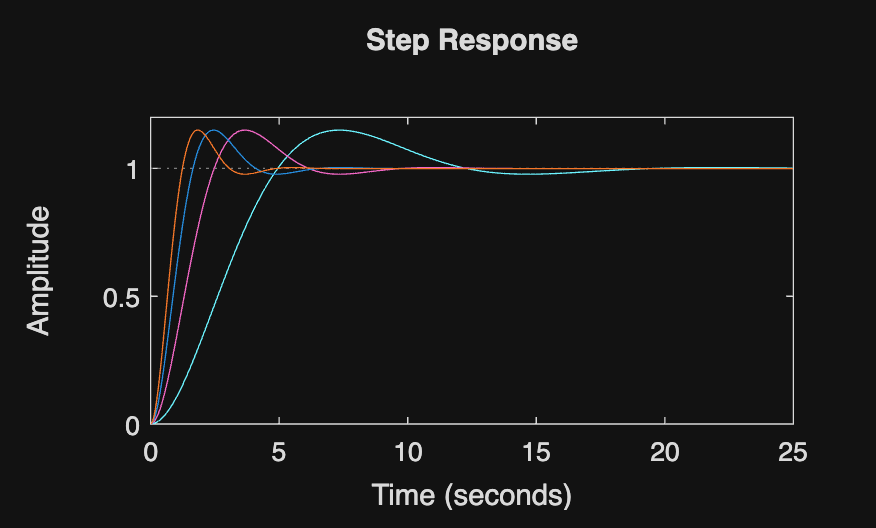


% display step response
step(second_order)

% show that w doesn't affect OS
for w = 0.5:0.5:2
    second_order = w^2/(s^2+2*zeta*w*s + w^2);
    step(second_order)
    hold all 
end

hold off; % clear hold for next plot

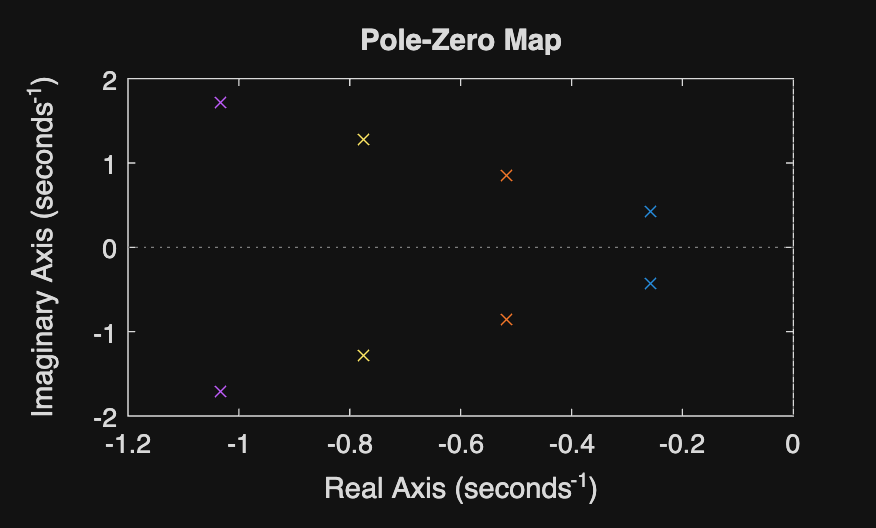

f = 5.1402

% see how poles and zeros move as w increases
for w = 0.5:0.5:2
    second_order = w^2/(s^2+2*zeta*w*s + w^2);
    pzmap(second_order)
    hold all 
end